# **Servo Motor System Identification Activity Sheet**

**Student Name**: Alex Ong

**Student Number: 12435562**

### **Preparations for the task:**

In preparation for these tasks, download the 4 functions (MATLAB content-obscured executable files) 

- `GenerateRandomData.p, `

- `GenerateUnknownData.p, `

- `GenerateSEASpeedData.p` and 

- `EGB345_DataNameChecker_SysId.p` 

from CANVAS and ensure they are in the appropriate MATLAB path. In some browsers, you might need to right-click your mouse and select the “Save Link as” option.  Place them in the same directory as this .mlx file.  

The next code helps prepare your MATLAB work space (you don't need to edit, unless error occurs)

%The next 3 lines change MATLAB's current working folder to this .mlx script's current location.
filePath = matlab.desktop.editor.getActiveFilename;
filePath = fileparts(filePath);
cd(filePath)
%If causes a MATLAB error on your computer, remove these 3 code lines and manually change folder.

clear all
close all

# Overview

This activity involves modelling a servo motor system, which includes a motor, an arm, and internal electronics. The goal is to estimate the parameters of the transfer function that describes the system's behaviour using experimental step response data. In last task of this activity we investigate a Series Elastic Actuator (see also Practical 1).

# Modelling the Servo motor

This task is based on a servo motor mechanism commonly used in remote control aircraft. Simply speaking, the servo system has a motor, an arm, and a set of internal electronics. The motor is used to induce rotary (or linear) motion of the arm. There is a sensor attached which measures shaft angular velocity.

**Transfer function modelling:**

The simplified transfer function, input voltage to angle, can be approximated by:

                                                        
$$G(s)=\frac{\Theta(s)}{V_m(s)}=\frac{K_m}{s(s+\alpha)}$$
                

where $V_m$ is input signal and $\Theta$ is output shaft position. The transfer function is characterised by two parameters,$K_m$ and $\alpha.$These $K_m$ and $\alpha$ parameters absorb the specific values of the internal physical constants such as motor constants, the inertia of the load and the gear ratio that we saw in lecture slides and tutorial problems. IN a real setting, these $k_m$ and $\alpha$ parameters are not initially known.

**Experiment-based modelling with quantitative and qualitative assessment**

In this system identification task, we will use an **experiment-based modelling** approach in which we estimate the unknown  $K_m$ and $\alpha$ parameters of the transfer function from experimental capture step response data. An example of this step response datais the step time response to a *2V step response* shown in Figure 1 below.

In this system identification task, you will aim to have a good estimate the$k_m$ and $\alpha$parameters so that the **step response of the estimated **  best** matches** the step response data. A well-estimated servo motor model will mean that its step response has a good match with step response data.

In evaluating your performance at this system identification task, you will make both **quantitative** and** qualitative** **assessments**of the match of your estimated model to the step response data. In this context, the word `quantitative’ will refer to quantities (as in numbers) whilst the word `qualitative’ will refer to qualities (as in features or appearance).

# Assessed Questions

Complete the following 4 tasks. The provided .p functions will generate data unique to you.

## Task 1 (Data Plot):

#### Task 1.1: [Generate data] 

Create your randomly assigned data using the following MATLAB command:

***ANSWER (edit below code block)***

%Edit with your student number
yourstudentnumber=12435562;
[km, alpha] = GenerateRandomData('EGB345RandomData.csv',yourstudentnumber)

km = 9.7633

alpha = 4.5932

where `yourstudentnumber `is replaced by your student number.

This function will generate a CSV file (‘EGB345RandomData.csv’) that contains the following information:

- A time vector.

- Channel 1 is reading the 2V step response of motor speed. The angle have been measured by a potentiometer (has units of Volts).

Your true values of $K_m$ and $\alpha$ will also be stored in the variables ‘km’ and ‘alpha’, respectively. Please write these values down for your assessment submission.  Here “2V” means 2 Volt, and we highlight this is not a unit step input, which will impact your MATLAB code in later Tasks.

**Note: The GenerateRandomData ****function**** will generate different parameter values and noise values based on your student number.**

#### Task 1.2: [Read data]

Read the CSV file into your MATLAB workspace. The columns are labelled with text within the CSV file. This is to match the expected configuration as if you were taking these values from a real oscilloscope. 

***ANSWER (edit below code block)***

%edit here

servo_data = csvread('EGB345RandomData.csv',2,0);


#### **Task 1.3: [Plot data] **

Extract the original step response data (Channel 1) which you should name `'yn_random'`.   Plot Channel 1 versus the time vector. The plot of step response data will look qualitatively similar to the following when plotted. 

***ANSWER (edit below code block)***

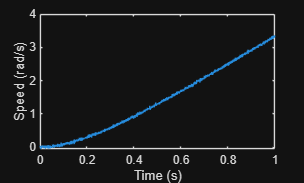

%edit here
second = servo_data(:,1);

yn_random = servo_data(:,2);

figure(122)

plot(second,yn_random)
xlabel('Time (s)')
ylabel('Speed (rad/s)')

%saveas(gcf, 'task1point3.png')

## Task 2 (Build and test your estimator):

Your task is to design and implement a technique to estimate the values of $K_m$ and $\alpha$ that were used to generate the 2V step response data `yn_random `(from the data `yn_random `itself). Specifically, you are seeking quantitatively accurate estimated parameters so that the estimated step response is qualitatively similar to the data.

Here, the words ‘**quantitatively accurate**’ mean the estimated parameter values are quantitative (or numerically) close to the true parameter values (parameter value error can be expressed either as an absolute amount or as a percentage). Here, the words ’**qualitatively similar**’ mean that when plotted the estimated response has similar features to the data (the data `'yn_random' `in this task).

You are interested in both the quantitative and qualitatively properties of your estimate.

#### Task 2.1: [Compose Estimator] 

Write MATLAB code to estimate $K_m$ and $\alpha$ from data `yn_random. `Record your estimate. Provide an explanation of your estimation approach which addresses the following questions: What is your approach doing? Why is your approach useful? When might your approach not work? (200-400 words, indicative length).

Please use T2_km_est and T2_alpha_est as your variable names for your stimated model parameter values.

***ANSWER (edit below code block)***

%edit here
%T2_km_est=9.7
%T2_alpha_est=4.6

opt = stepDataOptions('StepAmplitude', 2);
oldCost = 1e100;

for alpha = 0.1:0.1:5
    for Km = 0.1:0.1:10
        sys  = tf(Km, [1 alpha 0]);
        test = step(sys, second, opt);
        test = test(1:length(yn_random));
        cost = rms(test - yn_random);
        if cost < oldCost
            T2_km_est = Km;
            T2_alpha_est = alpha;
            oldCost = cost;
        end
    end
end


***ANSWER (edit below text section)***

The code uses a nested for loop to iteratively search over a two-dimensional grid with dimensions Km and a. Within the for loop, a Km and a are paired and a candidate model is created and a step response is simulated. Using this approach we can get the most accurate pair of Km and a by keeping the pair with the lowest RMS error.

The grid search approach is useful as it is simple and doesn’t need derivatives or gradient information. Since it iterates over the specified intervals of 0.1 it will find the closest pair of values for the global minimum.

This approach may not work when the optimal pair lies in a grid point with higher precision than the proposed step size (0.1) or if the bounds lie outside the searched ranges.

#### Task 2.2: [Qualitative assessment] 

Visually confirm the qualitative quality of your estimate by plotting step response data `yn_random` (plotted in red) and the estimated step response using your estimated values of $K_m$ and $\alpha$ (plotted in blue) overlaying each other on the same plot versus time vector that highlights how well, or not, your estimated step response matches the data (that is, visually confirm the qualitative similarity of the estimated step response). (100-200 words, indicative length).

***ANSWER (edit below code block)***

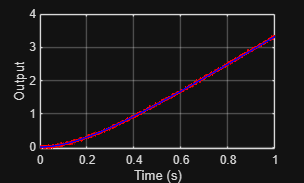

opt = stepDataOptions('StepAmplitude', 2);

sys_est = tf(T2_km_est, [1 T2_alpha_est 0]);
y_est   = step(sys_est, second, opt);
y_est   = y_est(1:length(yn_random));

figure;
plot(second(1:length(yn_random)), yn_random, 'r-', 'LineWidth', 1.2); hold on;
plot(second(1:length(yn_random)), y_est,     'b-', 'LineWidth', 1.2);
hold off;

xlabel('Time (s)');
ylabel('Output');
grid on;

***ANSWER (edit below text section)***

The plot contains the measured step response yn_random (red) with the simulated response of the estimated model G(s) (blue) over the same 2V step and time vector. Visually, the graph shows a close resemblance between yn_random and estimated values of Km and a. They both share a similar upwards trend yet there is a considerable amount of noise with yn_random graph. However, this does not indicate a poor fit as additionally the absence of large gaps further supports that they are visually qualitatively similar.

#### Task 2.3: [Quantitative assessment] 

Comment on why/if your parameter estimates are quantitative accurate and whether the estimated step response is qualitatively similar (100-200 words, indicative length). Your answer should reference the parameter errors, and the qualitative visual match between step response data `yn_random` and your estimated step response. (100-200 words, indicative length).

***ANSWER (edit below code block)***

%edit here




***ANSWER (edit below text section)***

<Edit Here>

## Task 3 (Challenge your estimator):

In this task we challenge your estimator on servo motor data with unknown parameters.

#### **Task 3.1: [Generate unique data] **

Create a second set of randomly assigned data using the following

MATLAB command:

GenerateUnknownData('EGB345UnknownData.csv',yourstudentnumber)

**The MATLAB code used to generate data will be unique to your student number and will have different (hidden) model parameters of 𝑲𝒎 and 𝜶. The generated data will correspond to the same sized step input as previous tasks (that is, 2V).**

You are required to conduct data analysis and estimate the model parameters of $K_m$ and $\alpha$. This will test whether your estimation process in Task 2 generalises to other sets of data.

#### Task 3.2: [Estimate Parameters] 

Adjust as necessary and apply your estimation code from Task 2. Record your estimated parameter values. Plot both the step response data from EGB345UnknownData (plotted in red) and your estimated model data (plotted in blue) on the same plot to highlight how well they match. 

Please use T3_km_est and T3_alpha_est as your variable names for your estimated model parameter values.

***ANSWER (edit below code block)***

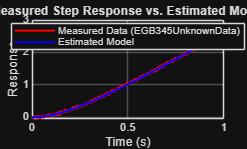

%edit here
%T3_km_est=9.7
%T3_alpha_est=4.6

unknownData = readmatrix('EGB345UnknownData.csv');

tv3   = unknownData(:,1);
data3 = unknownData(:,2);

opt_2 = stepDataOptions('StepAmplitude', 2);
oldCost_2 = 1e100;

for alpha_2 = 0.1:0.1:10
    for Km_2 = 0.1:0.1:20
        sys_2  = tf(Km_2, [1 alpha_2 0]);
        test_2 = step(sys_2, tv3, opt_2);
        test_2 = test_2(1:length(data3));
        cost_2 = rms(test_2 - data3);
        if cost_2 < oldCost_2
            T3_km_est    = Km_2;
            T3_alpha_est = alpha_2;
            oldCost_2 = cost_2;
        end
    end
end

sys_best = tf(T3_km_est, [1 T3_alpha_est 0]);

% Simulate its step response at the same time points as the real data
model_response = step(sys_best, tv3, opt_2);
model_response = model_response(1:length(data3));

% Plot measured data (red) and estimated model (blue) on the same axes
figure;
plot(tv3, data3, 'r', 'LineWidth', 1.5);
hold on;
plot(tv3, model_response, 'b', 'LineWidth', 1.5);
hold off;

xlabel('Time (s)');
ylabel('Response');
title('Measured Step Response vs. Estimated Model');
legend('Measured Data (EGB345UnknownData)', 'Estimated Model', 'Location', 'best');
grid on/;

***ANSWER (edit below text section)***

<Edit Here>

#### Task 3.3: [Qualitative and quantitative assessment]

In relation to your Task 3.2 parameter value estimates and plot, provide both:

- your assessment of the qualitative similarity of estimated step response, and

- your prediction of the quantitative accuracy of your parameter estimates (e.g. fpercentage error in each value).

Include justification for your assessment and prediction. (250-500 words, indicative length).

This question is asking you to provide both a **quantitative prediction **and a **qualitative assessment **informed by what you observed in Task 2 (where you knew parameter values). You don’t know the true situation here in Task 3, but you are asked to make reasonable inference of error in estimated parameters from your qualitative assessment of the estimated step response. This lack of parameter knowledge what occurs in a real-world setting.

Your quantitative prediction needs to be expressed as a quantity.

***ANSWER (edit below text section)***

<Edit Here>

## Task 4 (Harder challenge):

In practical 1 of EGB345 you were provided with the experimentally measured speed of the Series Elastic Actuator (SEA) output for 2V step input.

You are told the transfer function of the input voltage to the angle speed is given by:

                                                
$$\frac{\Omega_L(s)}{E_a(s)}=\frac{N_1}{s^3+D_3s^2+D_2s+D_1}$$


where some example system parameters are $N_1 \approx 4600$, $D_3 \approx 150$, $D_2\approx900$ and $D_1 \approx 40000$.  These are not the true values, as each student will have different values.

#### Task 4.1: [Generate unique data] 

Create a second set of randomly assigned data using the following

MATLAB command: 

GenerateSEASpeedData('EGB345SEASpeedData.csv',yourstudentnumber);

#### Task 4.2: [Compose Estimator] 

Write MATLAB code to estimate $N_1$, $D_3$, $D_2$  and $D_1$from the generated data. Record your estimated parameter values. Plot both the step response data from\ EGB345SEASpeedData (plotted in red) and your estimated model data (plotted in blue) on the same plot to highlight how well they match. 

Please use T4_N1_est, T4_D3_est, T4_D2_est and T4_D1_est as your variable names for your estimated model parameter values.

***ANSWER (edit below code block)***

%edit here
%T4_N1_est=1
%T4_D3_est=1
%T4_D2_est=1
%T4_D1_est=1

seaData = readmatrix('EGB345SEASpeedData.csv');

% Inspect column layout first if unsure:
% disp(seaData(1:5,:))

tv4    = seaData(:,1);
speed4 = seaData(:,2);

tv4    = tv4(:);
speed4 = speed4(:);

%% Task 4.2: Estimate N1, D3, D2, D1
opt4 = stepDataOptions('StepAmplitude', 2);   % 2V step

% --- Cost function: RMS error between model step response and data ---
% p = [N1, D3, D2, D1]
costFcn = @(p) rmsCost(p, tv4, speed4, opt4);

% --- Initial guess ---
% Use the example values given in the task as a starting point/order of
% magnitude reference (true values will differ per-student but should be
% in a broadly similar range/scale).
p0 = [4600, 150, 900, 40000];

% --- Optimize using fminsearch (Nelder-Mead, derivative-free) ---
options = optimset('Display','iter','MaxFunEvals',5000,'MaxIter',5000,'TolFun',1e-6,'TolX',1e-6);
[p_opt, finalCost] = fminsearch(costFcn, p0, options);

 
 Iteration   Func-count         f(x)         Procedure
     0            1         0.044728         
     1            5        0.0382982         initial simplex
     2            7        0.0216225         expand
     3            8        0.0216225         reflect
     4            9        0.0216225         reflect
     5           10        0.0216225         reflect
     6           12        0.0216225         contract inside
     7           14        0.0216225         contract inside
     8           16        0.0216225         contract outside
     9           18        0.0216225         contract inside
    10           20        0.0206851         reflect
    11           22        0.0206851         contract inside
    12           23        0.0206851         reflect
    13           24        0.0206851         reflect
    14           26        0.0203732         reflect
    15           27        0.0203732         reflect
    16           29        0.0203732         contract 


T4_N1_est = p_opt(1);
T4_D3_est = p_opt(2);
T4_D2_est = p_opt(3);
T4_D1_est = p_opt(4);

fprintf('T4_N1_est = %.3f\n', T4_N1_est);

T4_N1_est = 7576.339


fprintf('T4_D3_est = %.3f\n', T4_D3_est);

T4_D3_est = 261.219


fprintf('T4_D2_est = %.3f\n', T4_D2_est);

T4_D2_est = 1331.510


fprintf('T4_D1_est = %.3f\n', T4_D1_est);

T4_D1_est = 58424.609



% --- Sanity check: rerun from a few different starting points to check ---
% for convergence to (roughly) the same minimum, guarding against
% fminsearch landing in a poor local minimum
p0_alt = [3000, 100, 600, 30000];
[p_opt_alt, cost_alt] = fminsearch(costFcn, p0_alt, options);

 
 Iteration   Func-count         f(x)         Procedure
     0            1        0.0787407         
     1            5         0.072308         initial simplex
     2            7        0.0446458         expand
     3            8        0.0446458         reflect
     4            9        0.0446458         reflect
     5           11        0.0329193         expand
     6           13        0.0256192         reflect
     7           14        0.0256192         reflect
     8           16        0.0256192         contract inside
     9           18        0.0256192         contract inside
    10           20        0.0256192         contract inside
    11           21        0.0256192         reflect
    12           22        0.0256192         reflect
    13           24        0.0240268         contract inside
    14           26        0.0225977         reflect
    15           28        0.0223842         contract inside
    16           30        0.0223842         contract in

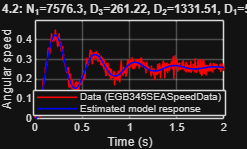

if cost_alt < finalCost
    warning('Alternative start point found a better fit — using that instead.');
    p_opt = p_opt_alt;
    T4_N1_est = p_opt(1); T4_D3_est = p_opt(2);
    T4_D2_est = p_opt(3); T4_D1_est = p_opt(4);
end

%% Plot: data (red) vs. estimated model (blue)
sys_est4 = tf(T4_N1_est, [1 T4_D3_est T4_D2_est T4_D1_est]);
y_est4   = step(sys_est4, tv4, opt4);
y_est4   = y_est4(1:length(speed4));

figure;
plot(tv4, speed4, 'r-', 'LineWidth', 1.2); hold on;
plot(tv4, y_est4, 'b-', 'LineWidth', 1.2);
hold off;

xlabel('Time (s)');
ylabel('Angular speed');
legend('Data (EGB345SEASpeedData)', 'Estimated model response', 'Location', 'best');
title(sprintf('Task 4.2: N_1=%.1f, D_3=%.2f, D_2=%.2f, D_1=%.1f', ...
    T4_N1_est, T4_D3_est, T4_D2_est, T4_D1_est));
grid on;


%% --- Local cost function (place at end of script / separate file) ---
function cost = rmsCost(p, tv, ydata, opt)
    N1 = p(1); D3 = p(2); D2 = p(3); D1 = p(4);
    sys = tf(N1, [1 D3 D2 D1]);
    try
        ymodel = step(sys, tv, opt);
        ymodel = ymodel(1:length(ydata));
        cost = rms(ymodel - ydata);
    catch
        cost = 1e10;   % penalize invalid/unstable parameter combos heavily
    end
end

***ANSWER (edit below text section)***

<Edit Here>

#### Task 4.3: [Qualitative and quantitative assessment]

In relation to your Task 4.2 parameter value estimates and plot, provide both:

- your assessment of the qualitative similarity of estimated step response (including determining the poles of your estimated transfer function, checking with the final value theorem, and using any relevant dominant poles considerations), and

- your prediction of the quantitative accuracy of your parameter estimates (e.g. percentage error in each value).

Include justification for your assessment and prediction (250-500 words, indicative length).

This question is asking you to provide both a **quantitative prediction** and a **qualitative assessment **informed by what you observed in Task 2 (where you knew parameter values). You don’t know the true situation here in Task 4, but you are asked to make reasonable inference of error in estimated parameters from your qualitative assessment of the estimated step response.  This lack of parameter knowledge is what occurs in a real-world setting.

Your quantitative prediction needs to be expressed as a quantity.

***ANSWER (edit below text section)***

<Edit Here>

#### Task 4.4 [Reflections on Task difficult relative to earlier tasks] 

Provide reflections on the relative estimation difficulty of Task 4 compared to Task 3. These reflections should include both qualitative and quantitative aspects.

***ANSWER (edit below text section)***

<Edit Here>

# Do not change below: Check for "Ready to Submit". 

This script checks your code's variable names. Will confirm if ready to submit. Creates a design summary that is used to evaluate your activity.

EGB345_DataNameChecker_SysId

Checking your code. Will create design summary if valid.


Design Summary (for use in marking, checked for correct variable names)

yourstudentnumber=12435562
km=9.763301 
alpha=5.000000
T2_km_est=9.900000 
T2_alpha_est=4.700000
T3_km_est=8.000000 
T3_alpha_est=4.900000
T4_N1_est=7576.338911 
T4_D3_est=261.219317 
T4_D2_est=1331.510175 
T4_D1_est=58424.609132


Congratulations. Ready for submission.
